# Circulation

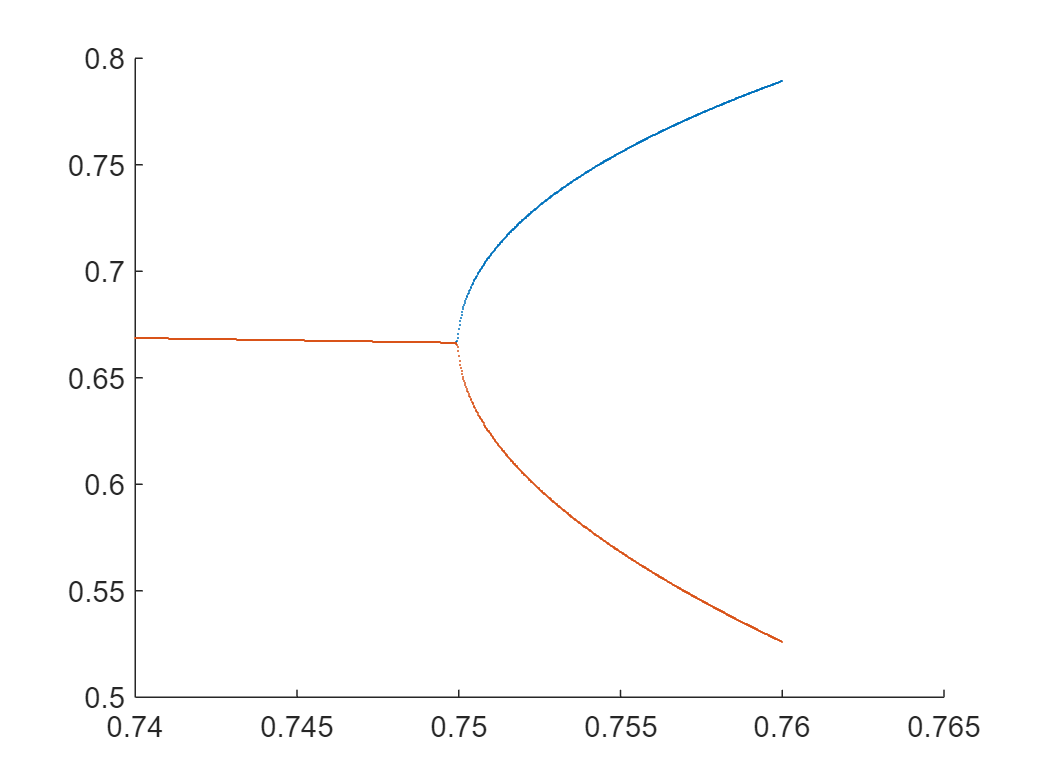

t=200;
l=1000;
w=zeros(l+1,t);
cir=50000;
bn=cir-t+1;
k_temp=linspace(0.74,0.76,l+1);
for i=1:1:l+1
    k=k_temp(i);
    x=chaos1((-1+sqrt(4.2))/1.6,k,cir);
    w(i,:)=x(bn:cir);
end
P=findpeak(w,1,t);
figure(2)
scatter(k_temp,P(:,end-50:end),0.5,'filled')

## Function

function x=chaos1(x1,k,cir)
x(1)=x1;
x=[x(1),zeros(1,cir)];
for i=1:cir
    x(i+1)=1-k*x(i)^2;
end
end

function P=findpeak(w,bn,en)
[m,~]=size(w);
for i=1:m
    x=bn+1;
while x <= en-1
    if (w(i,x-1)-w(i,x))*(w(i,x)-w(i,x+1)) <= 0
       P(i,x)=w(i,x);
    else
       P(i,x)=NaN;
    end
    x=x+1;
end
end
end